load("pots.mat")
load("pots_cut.mat")
syms x y
assume(x, 'real')
assume(y, 'real')

%Function of the mountain
% f = 16*exp(-x.^2./2-y.^2./2-x.*y./2) + 4*exp(-(x+1.5).^2 - (y+2.5).^2);
[dx,dy] = gradient(pots_final);
% [dx,dy] = gradient(pots_cut);
% [dx,dy] = gradient(pots_test);

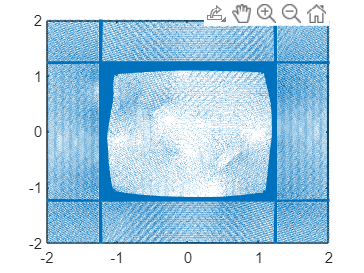

quiver(X,Y, dx, dy, 20)
axis([-2 2 -2 2])

clf


%Declare initial values
r_x = 0.933;
r_y = 0.838;
% lambda = 0.03;
% delta = 0.37;
lambda = 0.03;
delta = 0.5;
r_xes = [r_x; 0]; %Matrix to store x positions
r_yes = [r_y; 0]; %Matrix to store y positions

max_count = 15;
count = 1;
% grad_r = double(subs(grad, {x, y}, {r_x, r_y}));
x_idx = find(abs(X(1,:) - r_x) < (0.0125/2))

x_idx = 236

y_idx = find(abs(Y(:,1) - r_y) < (0.0125/2))

y_idx = 228

grad_r = [dx(y_idx, x_idx); dy(y_idx, x_idx)];

%Calculate every position the Neato using gradient ascent
%Store the x,y positions in a matrix
while abs(norm(grad_r)) > 0.00001 && count <= max_count
    count = count + 1;
    if r_x < -1.3
        r_x = -1.3;
    end
    if r_x > 1.1
        r_x = 1.1;
    end
    if r_y > 1.1
        r_y = 1.1;
    end
    if r_y < -1.2
        r_y = -1.2;
    end
    x_idx = find(abs(X(1,:) - r_x) <= (0.0125/2));
    y_idx = find(abs(Y(:,1) - r_y) <= (0.0125/2));
    grad_r = [dx(y_idx, x_idx); dy(y_idx, x_idx)];
    r_x = r_x + lambda*grad_r(1); %Find x
    r_y = r_y + lambda*grad_r(2); %Find y
    lambda = delta * lambda; %update lambda
    r_xes(count) = r_x;
    r_yes(count) = r_y;
end

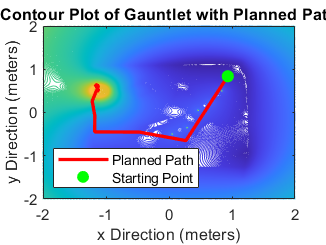

figure()
contour(X,Y,pots_final,500)
hold on
plot(r_xes, r_yes, "r", "LineWidth", 2)
start_x = 0.933;
start_y = 0.838;
plot(start_x, start_y, "g.", "MarkerSize", 25)
legend("", "Planned Path", "Starting Point","Location", "Southwest")
xlabel("x Direction (meters)")
ylabel("y Direction (meters)")
title("Contour Plot of Gauntlet with Planned Path")
hold off
save("path.mat", "r_xes", "r_yes")
axis([-2 2 -2 2]);